# Computing Probabilities with Continuous Distributions

## Normal Distribution

An automotive engineer has determined that the fuel economy for a prototype of a new truck can be modeled with a normally distributed random variable with a mean of 17.3 miles per gallon with a standard deviation of 2.7 (this accounts for variations in fuel economy that result from different driving conditions). When asked what the probability is that tht fuel economy would fall between 15 and 16 $(15<x<16)$ miles per gallon at any particular moment, she responded by performing the following calculation:

P=normcdf(16,17.3,2.7)-normcdf(15,17.3,2.7)

P = 0.1179

A census worker has learned that human life expectancy in his arena of study is a normally distributed random variable witha mean value of 81.35 years and a standard deviation of 11.64 years. Therefore, the probability any given person in that region will live more than 90 years $(x>90)$ is

P=normcdf(90,81.35,11.64,'upper')

P = 0.2287

## Sampling and the Central Limit Theorem

A market researcher is analyzing the results of an experiment in which the heights of random samples of 10 people were measured. Even though the researcher does not have a model for the distribution of height measurements, she has already estimated that the mean of this unknown distribution in $\mu\simeq 5.6934$ and the standard deviation is $\sigma\simeq 0.7999$. The researcher hopes to determine the probability of obtaining a sample of heights with a mean greater than 6 feet. Since her sample size is $n=10$, she invokes the Central Limit Theorem and concludes that thte variation in the sample means is described by a normal distribution with $\mu\simeq 5.6934$ and $\sigma\simeq 0.7999/\sqrt{10}\simeq 0.2530$. Therefore, the probability that the mean of any given sample is greater than 6 feet is

P=normcdf(6,5.6934,0.2530,'upper')

P = 0.1128

A water quality technician is attempting to assess claims made by a property owner that they have addressed problems with their septic system and that nitrate levels down-gradient from their system are now averaging at 

mu=10

mu = 10

parts per million. The technician takes 15 independent nitrate measurements from a test well down-gradient of the septic system and finds the following levels (in parts per million):

D=[14.7137, 13.8745, 10.7293, 8.7689, 14.8821, 9.6489, 15.1748, 12.2348, 12.1531, 13.6441, 14.7137, 13.8745, 10.7293, 8.7689, 14.8821, 9.6489, 15.1748, 12.2348, 12.1531, 13.6441]

D =    14.7137   13.8745   10.7293    8.7689   14.8821    9.6489   15.1748   12.2348   12.1531   13.6441   14.7137   13.8745   10.7293    8.7689   14.8821    9.6489   15.1748   12.2348   12.1531   13.6441


He computes the mean of this sample to find that 

xb=mean(D)

xb = 12.5824

From earlier analysis, the technician knows that the standard deviation of the nitrate measurements is 

sigma=2.3

sigma = 2.3000

With this information and the landowner's claim that the down-gradient concentrations are now averaging at 10 parts per million.  The technician computes a z statistic for this sample.

z=(xb-mu)/(sigma/sqrt(length(D)))

z = 5.0213

The technician suspects that it is unlikely that the landowner's claim is true, but in order to quantify this, he observes that the probability that $z$ should be found at or above the value she calcluated is small:

normcdf(z,'upper')

ans = 2.5665e-07

Thsi is a very small probablity, so she concludes that the landowner's claim is unlikely to be true.

# $\chi^2$ Distribution

A manufacturer of gold ingots desires to maintain a high degree of consistency in the mass of the ingots they produce. The mean weight of the ingots is taken to be 

mu=1000

mu = 1000

grams. The plant manager will consider that the production consistency of gold ingots is out of tolerance if he has reason to believe that the true value of the standard deviation of ingot masses is more than 0.001 grams. In order to determine whether or not this is the case, the plant manager requires that an occasional sample of 

n=25

n = 25

ingots will be randomly sampled so that their masses may be precisely measured.

Suppose one such sample is collected and its sample standard deviation turns out to be 

s=0.0015

s = 0.0015

The $\chi^2$ statistic for this scenario is


$$\chi^2=\frac{(n-1)s^2}{\sigma^2}=\frac{24\times 0.0015^2}{0.001^2}$$


`or`

chi2=24*(0.0015^2)/(0.001^2)

chi2 = 54

Using the $\chi^2$ distribution with

nu=24

nu = 24

degrees of freedom, the plant manager determines that the probability of observing a sample with a sample standard deviation of at least 0.0015 is

P =chi2cdf(chi2,24,'upper')

P = 4.2624e-04

which is quite small. The manager concludes that this sample is indicative that production quality might be out of tolerance.

# Student's T Distribution

An agricultural engineer is investigating the performance claims made by a chemical company that produces fertilizers. They state that under typical conditions, addition of their fertilizer to a one acre plot of potatoes will result in an average yield of 32.8 thousand pounds. The engineer prepares five separate one acre plots and applies the fertilizer to all of them. At the end of the growing season, these fields yield 

D=[29.28, 28.84, 28.86, 28.47, 30.84]

D =    29.2800   28.8400   28.8600   28.4700   30.8400


thousand pounds of potatoes respectively.

The engineer calculates the mean and variance of the data:

xb=mean(D)

xb = 29.2580

s=std(D)

s = 0.9297

Then, she computes the t statistic for this data with 

nu=length(D)-1

nu = 4

degrees of freedom and the claimed yield of 

mu=32.8

mu = 32.8000

thousand pounds per acre:

t=(xb-mu)/(s/sqrt(length(D)))

t = -8.5192

The fact that $t<0$ reflects the reality that the sample mean lies below the proposed true mean of 32.8 thousand pounds per acre. She plots the t distribution for $\nu=4$ degrees of freedom and observes that $t=-8.5192$ is well out into the lower tail.

tdata=linspace(-10,10,100)

tdata =   -10.0000   -9.7980   -9.5960   -9.3939   -9.1919   -8.9899   -8.7879   -8.5859   -8.3838   -8.1818   -7.9798   -7.7778   -7.5758   -7.3737   -7.1717   -6.9697   -6.7677   -6.5657   -6.3636   -6.1616   -5.9596   -5.7576   -5.5556   -5.3535   -5.1515   -4.9495   -4.7475   -4.5455   -4.3434   -4.1414   -3.9394   -3.7374   -3.5354   -3.3333   -3.1313   -2.9293   -2.7273   -2.5253   -2.3232   -2.1212   -1.9192   -1.7172   -1.5152   -1.3131   -1.1111   -0.9091   -0.7071   -0.5051   -0.3030   -0.1010


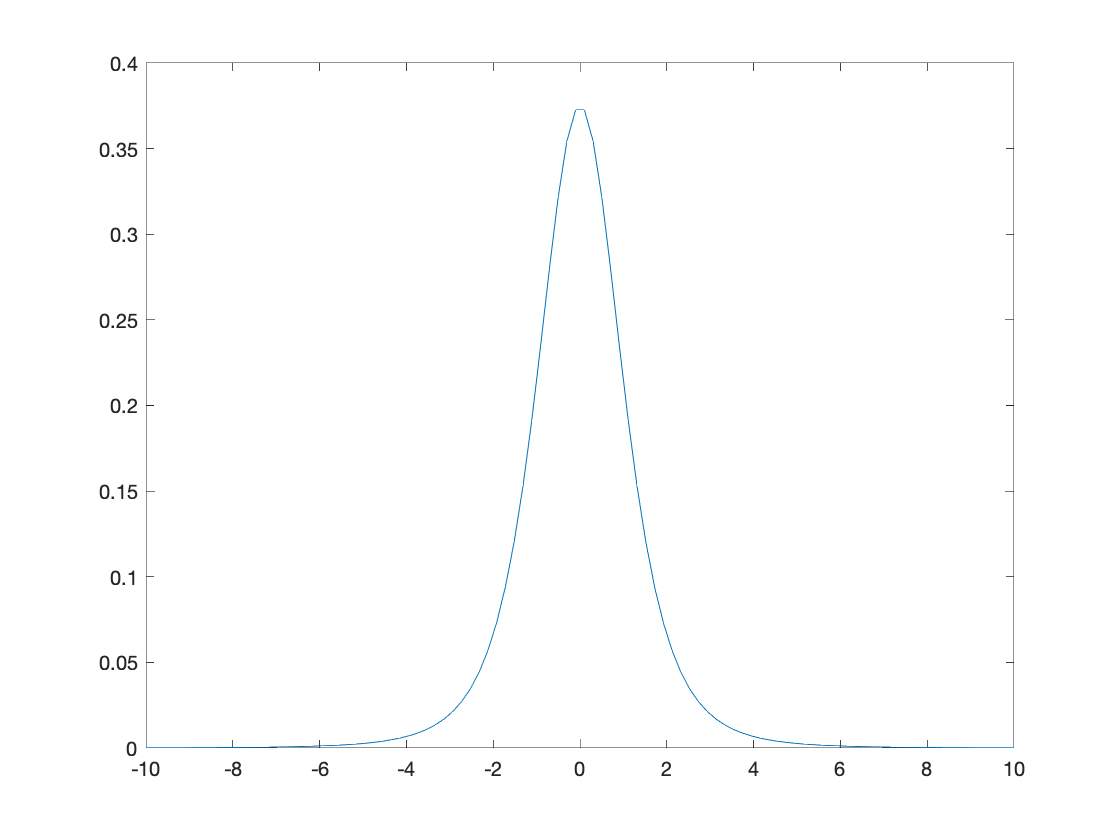

plot(tdata,tpdf(tdata,nu))

She computes the probability of obtaining a sample with a t statistic at least as extreme as the one she computed:

P=tcdf(t,nu)

P = 5.2079e-04

This is quite small, so she concludes that it is unlikely that her fertilizer is performing as advertised.